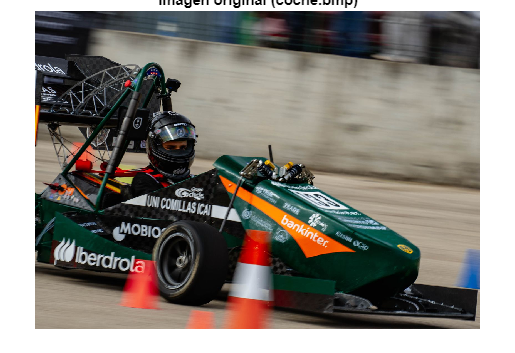

%% 1.a) Carga y representación de la imagen + comparación de tamaños

clear; close all; clc;

% Elegimos una imagen no comprimida (por ejemplo coche.bmp)
img_color = imread('coche.bmp');

% Mostramos la imagen original
figure('Name','Imagen original','NumberTitle','off','Position',[100 100 900 600]);
imshow(img_color);
title('Imagen original (coche.bmp)');


% Comprobamos tamaño y dimensiones
info_color = dir('coche.bmp');
[tam_y, tam_x, canales] = size(img_color);
fprintf('Imagen original: %d x %d píxeles, %d canales, %.2f KB\n', ...
        tam_x, tam_y, canales, info_color.bytes/1024);

Imagen original: 1600 x 1143 píxeles, 3 canales, 5357.95 KB



% Si la imagen tiene 3 canales, la pasamos a escala de grises
if ndims(img_color) == 3
    img_gray = rgb2gray(img_color);
else
    img_gray = img_color;
end

% Guardamos la imagen en escala de grises para comparar tamaños
imwrite(img_gray, 'coche_gris.bmp');
info_gray = dir('coche_gris.bmp');

fprintf('Imagen en escala de grises: %d x %d píxeles, 1 canal, %.2f KB\n', ...
        size(img_gray,2), size(img_gray,1), info_gray.bytes/1024);

Imagen en escala de grises: 1600 x 1143 píxeles, 1 canal, 1786.99 KB


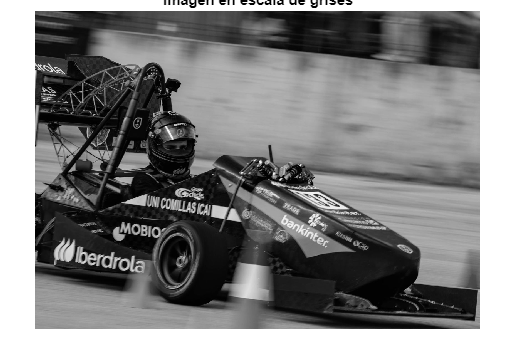


% Mostramos la imagen en escala de grises
figure('Name','Imagen gris','NumberTitle','off','Position',[200 200 900 600]);
imshow(img_gray);
title('Imagen en escala de grises');

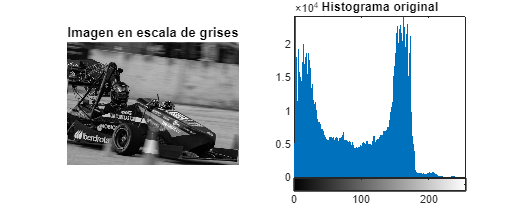

%% 1.b) Histograma y posible ajuste de escala

figure('Name','Histogramas','NumberTitle','off','Position',[100 100 1200 500]);
subplot(1,2,1);
imshow(img_gray);
title('Imagen en escala de grises');

subplot(1,2,2);
imhist(img_gray);
title('Histograma original');


% Cálculo de mínimos y máximos
min_val = double(min(img_gray(:)));
max_val = double(max(img_gray(:)));
fprintf('Valor mínimo de gris: %.0f\n', min_val);

Valor mínimo de gris: 0


fprintf('Valor máximo de gris: %.0f\n', max_val);

Valor máximo de gris: 254


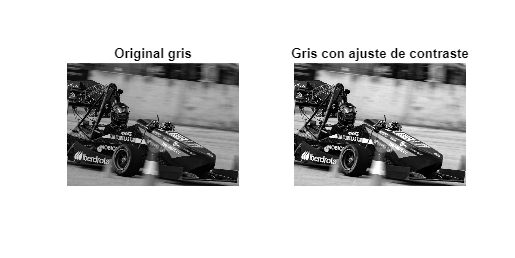


% Ajuste automático de contraste si no usa todo el rango
img_gray_adj = imadjust(img_gray);

figure('Name','Ajuste de contraste','NumberTitle','off','Position',[150 150 1200 600]);
subplot(1,2,1);
imshow(img_gray);
title('Original gris');

subplot(1,2,2);
imshow(img_gray_adj);
title('Gris con ajuste de contraste');

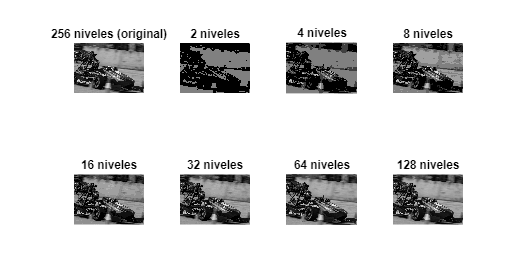

%% 1.c) Deterioro con diferente número de niveles de gris

niveles = [2 4 8 16 32 64 128];

figure('Name','Cuantización a diferentes niveles','NumberTitle','off','Position',[50 50 1300 700]);
subplot(2,4,1);
imshow(img_gray);
title('256 niveles (original)');

for k = 1:length(niveles)
    L = niveles(k);
    img_q = uint8( floor(double(img_gray) / 256 * L) * (256 / L) );

    subplot(2,4,k+1);
    imshow(img_q);
    title(sprintf('%d niveles', L));
end

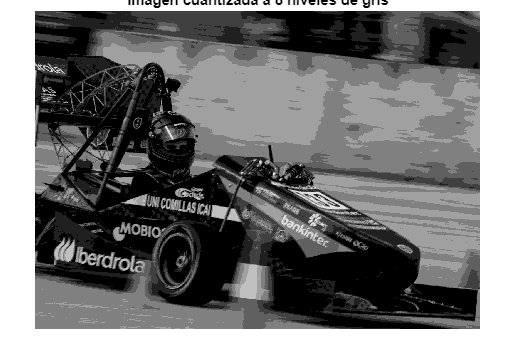

%% 2.a) Imagen con solo 8 niveles de gris y tabla de Huffman

% Partimos de img_gray (asegúrate de ejecutar antes la parte 1)
if ~exist('img_gray','var')
    error('img_gray no existe. Ejecuta antes el apartado 1.');
end

% Cuantización uniforme a 8 niveles (0..7)
L = 8;
img8 = floor(double(img_gray) / 256 * L);   % valores 0..7

% Mostramos la imagen cuantizada
figure('Name','Imagen 8 niveles','NumberTitle','off','Position',[100 100 900 600]);
imshow(uint8(img8 * (256/L)));  % reescalamos para visualizar
title('Imagen cuantizada a 8 niveles de gris');


% Cálculo de la probabilidad de cada símbolo
symbols = 0:L-1;
[counts, ~] = histcounts(img8(:), -0.5:1:(L-0.5));
p = counts / sum(counts);

% Eliminamos símbolos con probabilidad 0 (por si acaso)
nz_idx = p > 0;
sym_nz = symbols(nz_idx);
p_nz = p(nz_idx);

% Construcción de la tabla de Huffman
[dict, avglen] = huffmandict(sym_nz, p_nz);

% Mostramos tabla en consola
disp('Tabla de codificación de Huffman (símbolo -> código):');

Tabla de codificación de Huffman (símbolo -> código):


for i = 1:length(sym_nz)
    codigo = dict{i,2};
    fprintf('Símbolo %d : ', dict{i,1});
    fprintf('%d', codigo);
    fprintf('\n');
end

Símbolo 0 : 

01

Símbolo 1 : 

001

Símbolo 2 : 

111

Símbolo 3 : 

1100

Símbolo 4 : 

10

Símbolo 5 : 

000

Símbolo 6 : 

11010

Símbolo 7 : 

11011


fprintf('Longitud media de código de Huffman: %.4f bits/símbolo\n', avglen);

Longitud media de código de Huffman: 2.6338 bits/símbolo



% Guardamos por si se usa después:
img8_symbols = img8(:);  % vector de símbolos 0..7

%% 2.b) Codificación Huffman de la imagen de 8 niveles

% Codificamos usando el diccionario obtenido
encoded = huffmanenco(img8_symbols, dict);

% Mostramos algunos datos
num_pix = numel(img8_symbols);
bits_huffman = length(encoded);

fprintf('\n--- Codificación Huffman ---\n');


--- Codificación Huffman ---


fprintf('Número de píxeles: %d\n', num_pix);

Número de píxeles: 1828800


fprintf('Bits totales con Huffman: %d\n', bits_huffman);

Bits totales con Huffman: 4816632


fprintf('Bits medios por píxel con Huffman: %.4f\n', bits_huffman/num_pix);

Bits medios por píxel con Huffman: 2.6338


%% 2.c) Decodificación Huffman y reconstrucción de la imagen

decoded_symbols = huffmandeco(encoded, dict);

% Comprobamos que coincide con el original cuantizado
if isequal(decoded_symbols, img8_symbols)
    disp('Decodificación correcta: la imagen recuperada coincide con la cuantizada original.');
else
    warning('La imagen decodificada NO coincide con la original cuantizada.');
end

Decodificación correcta: la imagen recuperada coincide con la cuantizada original.


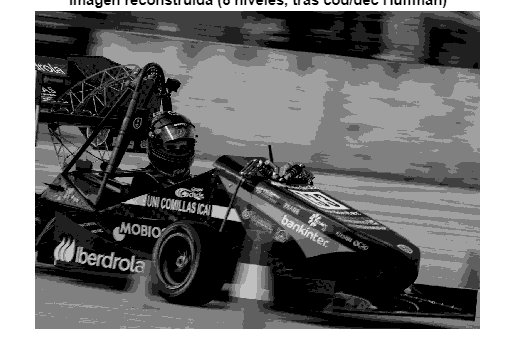


% Reconstruimos la imagen 2D
img8_rec = reshape(decoded_symbols, size(img8));

figure('Name','Imagen reconstruida tras Huffman','NumberTitle','off','Position',[150 150 900 600]);
imshow(uint8(img8_rec * (256/L)));
title('Imagen reconstruida (8 niveles, tras cod/dec Huffman)');

%% 2.d) Ratio de compresión respecto a la imagen con 8 niveles (3 bits/píxel)

bits_original_8niveles = num_pix * 3;  % 3 bits por píxel (para 8 símbolos posibles)
Rc = bits_original_8niveles / bits_huffman;

fprintf('\n--- Ratio de compresión ---\n');


--- Ratio de compresión ---


fprintf('Bits original (8 niveles, 3 bits/píxel): %d\n', bits_original_8niveles);

Bits original (8 niveles, 3 bits/píxel): 5486400


fprintf('Bits Huffman: %d\n', bits_huffman);

Bits Huffman: 4816632


fprintf('Ratio de compresión Rc = Bits_original / Bits_Huffman = %.4f\n', Rc);

Ratio de compresión Rc = Bits_original / Bits_Huffman = 1.1391


%% 2.e) Redundancia de datos para el caso de 8 niveles

% Entropía de la fuente (solo símbolos con p>0)
H = -sum(p_nz .* log2(p_nz));

% Redundancia absoluta (bits "de más" respecto a código fijo de 3 bits)
R_abs = 3 - H;

% Redundancia relativa (porcentaje)
R_rel = R_abs / 3;  % también se puede expresar en %

fprintf('\n--- Redundancia ---\n');


--- Redundancia ---


fprintf('Entropía H = %.4f bits/símbolo\n', H);

Entropía H = 2.5547 bits/símbolo


fprintf('Redundancia absoluta R = 3 - H = %.4f bits/símbolo\n', R_abs);

Redundancia absoluta R = 3 - H = 0.4453 bits/símbolo


fprintf('Redundancia relativa = %.2f %%\n', R_rel*100);

Redundancia relativa = 14.84 %


fprintf('Longitud media Huffman = %.4f bits/símbolo (debería acercarse a H)\n', avglen);

Longitud media Huffman = 2.6338 bits/símbolo (debería acercarse a H)


%% 3.a) DCT 8x8 sobre la imagen cuantizada a 8 niveles (con padding correcto)

if ~exist('img8','var')
    error('img8 no existe. Ejecuta antes el apartado 2 (cuantización a 8 niveles).');
end

% Tamaño original
[rows_orig, cols_orig] = size(img8);

% Hacemos padding para que filas y columnas sean múltiplos de 8
pad_r = mod(8 - mod(rows_orig,8), 8);
pad_c = mod(8 - mod(cols_orig,8), 8);

img8_padded = padarray(img8, [pad_r pad_c], 'replicate', 'post');

[rows, cols] = size(img8_padded);
fprintf('Imagen 8 niveles: %d x %d (original), %d x %d (con padding)\n', ...
        rows_orig, cols_orig, rows, cols);

Imagen 8 niveles: 1143 x 1600 (original), 1144 x 1600 (con padding)



% Convertimos a double para la DCT
img8_d = double(img8_padded);

% DCT 2D por bloques 8x8
funDCT = @(block_struct) dct2(block_struct.data);
C = blockproc(img8_d, [8 8], funDCT);

% Mostramos un bloque 8x8 de ejemplo
ejemplo_bloque = C(1:8, 1:8);
disp('Bloque DCT 8x8 de ejemplo (esquina superior izquierda):');

Bloque DCT 8x8 de ejemplo (esquina superior izquierda):


disp(ejemplo_bloque);

   16.0000         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0



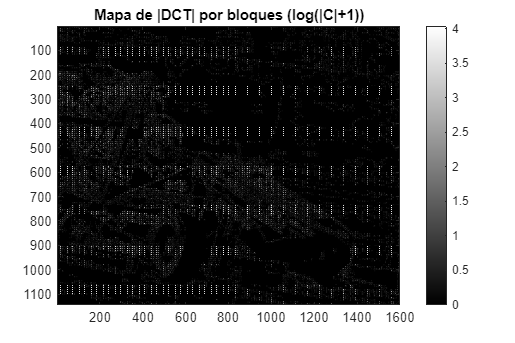


% Visualización de coeficientes (magnitud en log)
figure('Name','Coeficientes DCT (magnitud)','NumberTitle','off','Position',[100 100 900 600]);
imagesc(log(abs(C) + 1));
colormap gray; colorbar;
title('Mapa de |DCT| por bloques (log(|C|+1))');

%% 3.b) Análisis de ratio de compresión aproximado con distintas máscaras

num_pix_orig = rows_orig * cols_orig;
num_pix_pad = rows * cols;
num_bloques = num_pix_pad / (8*8);

% Orden zig-zag estándar 8x8 (índices lineales 1..64)
zigzag = [ ...
     1  2  9 17 10  3  4 11 ...
    18 25 33 26 19 12  5  6 ...
    13 20 27 34 41 49 42 35 ...
    28 21 14  7  8 15 22 29 ...
    36 43 50 57 58 51 44 37 ...
    30 23 16 24 31 38 45 52 ...
    59 60 53 46 39 32 40 47 ...
    54 61 62 55 48 56 63 64];

% Números de coeficientes significativos por bloque que vamos a conservar
K_vals = [64 32 16 10 6];

fprintf('\n--- Análisis DCT: Ratio de compresión aproximado ---\n');


--- Análisis DCT: Ratio de compresión aproximado ---


bits_original_8niv = num_pix_orig * 3;  % 3 bits/píxel (8 niveles)

for K = K_vals
    % Coeficientes almacenados total
    coefs_tot = num_bloques * K;

    % Suposición simple: cada coeficiente codificado con 3 bits (misma profundidad)
    bits_DCT = coefs_tot * 3;

    % Ratio de compresión tomando como referencia la imagen original 8 niveles (sin padding)
    Rc = bits_original_8niv / bits_DCT;

    fprintf('K = %2d coef/bloque -> Bits ≈ %d, Rc ≈ %.2f\n', K, bits_DCT, Rc);
end

K = 64 coef/bloque -> Bits ≈ 5491200, Rc ≈ 1.00
K = 32 coef/bloque -> Bits ≈ 2745600, Rc ≈ 2.00
K = 16 coef/bloque -> Bits ≈ 1372800, Rc ≈ 4.00
K = 10 coef/bloque -> Bits ≈ 858000, Rc ≈ 6.39
K =  6 coef/bloque -> Bits ≈ 514800, Rc ≈ 10.66



disp('Nota: es una estimación ideal, sin cabeceras ni codificación entropía sobre coeficientes.');

Nota: es una estimación ideal, sin cabeceras ni codificación entropía sobre coeficientes.


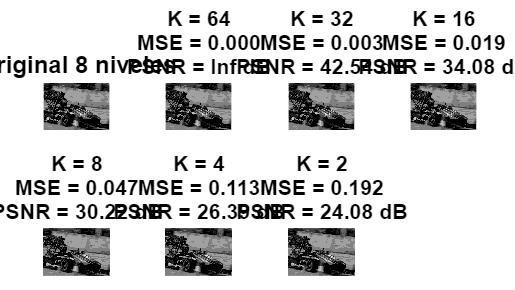

DCT K=64 -> MSE=0.0000, PSNR=Inf dB
DCT K=32 -> MSE=0.0027, PSNR=42.54 dB
DCT K=16 -> MSE=0.0191, PSNR=34.08 dB
DCT K= 8 -> MSE=0.0465, PSNR=30.22 dB
DCT K= 4 -> MSE=0.1125, PSNR=26.39 dB
DCT K= 2 -> MSE=0.1916, PSNR=24.08 dB


%% 3.c) Reconstrucción DCT con diferentes máscaras (versión corregida con reset)

close all  % <- Cierra todas las figuras previas (evita conflicto)
K_vals = [64 32 16 8 4 2];
L = 8;
max_val = L - 1;

fig_dct = figure('Name','Reconstrucción DCT (Extrema)','NumberTitle','off');
set(fig_dct, 'Units','normalized', 'OuterPosition',[0 0 1 1], 'Color','w');

% Aumentamos a 2x4 (8 huecos) por seguridad
tiledlayout(2,4, 'Padding','compact', 'TileSpacing','compact');

% Imagen original
nexttile;
imshow(uint8(img8 * (256/L)), 'InitialMagnification','fit');
title('Original 8 niveles', 'FontSize',18,'FontWeight','bold');

for idx = 1:length(K_vals)
    K = K_vals(idx);

    maskK = zeros(8,8);
    maskK(zigzag(1:K)) = 1;

    funMask = @(block_struct) block_struct.data .* maskK;
    C_masked = blockproc(C, [8 8], funMask);
    funIDCT = @(block_struct) idct2(block_struct.data);
    img_rec_padded = blockproc(C_masked, [8 8], funIDCT);
    img_rec = img_rec_padded(1:rows_orig, 1:cols_orig);

    img_rec_q = round(img_rec);
    img_rec_q(img_rec_q < 0) = 0;
    img_rec_q(img_rec_q > max_val) = max_val;
    img_show = uint8(img_rec_q * (256/L));

    diff = double(img8) - double(img_rec_q);
    MSE = mean(diff(:).^2);
    if MSE == 0, PSNR = Inf; else, PSNR = 10*log10((max_val^2)/MSE); end

    nexttile;
    imshow(img_show, 'InitialMagnification','fit');
    title(sprintf('K = %d\nMSE = %.3f\nPSNR = %.2f dB', ...
          K, MSE, PSNR), 'FontSize',16,'FontWeight','bold');

    fprintf('DCT K=%2d -> MSE=%.4f, PSNR=%.2f dB\n', K, MSE, PSNR);
end

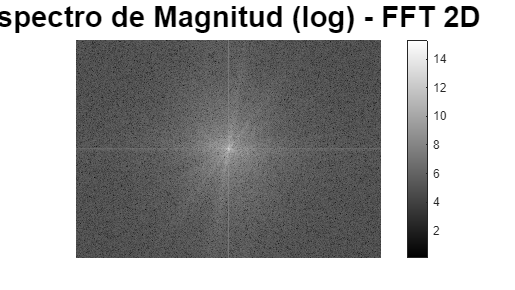

%% 4.a) FFT 2D con recortes más agresivos

if ~exist('img8_padded','var')
    [rows_orig, cols_orig] = size(img8);
    pad_r = mod(8 - mod(rows_orig,8), 8);
    pad_c = mod(8 - mod(cols_orig,8), 8);
    img8_padded = padarray(img8, [pad_r pad_c], 'replicate', 'post');
end

[Ny, Nx] = size(img8_padded);
L = 8; max_val = L - 1;

F = fft2(double(img8_padded));
F_shift = fftshift(F);

% Espectro (grande)
fig_fft1 = figure('Name','Espectro FFT','NumberTitle','off');
set(fig_fft1, 'Units','normalized', 'OuterPosition',[0 0 1 1], 'Color','w');
imagesc(log(abs(F_shift) + 1));
colormap gray; colorbar;
axis image off;
title('Espectro de Magnitud (log) - FFT 2D', 'FontSize',22,'FontWeight','bold');

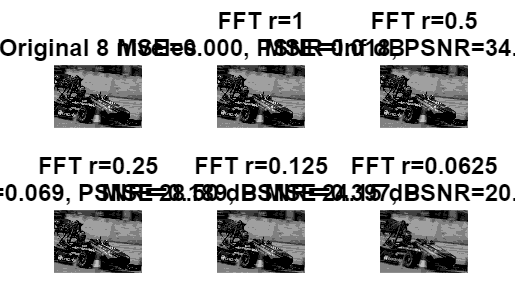

FFT r=1 -> MSE=0.0000, PSNR=Inf dB
FFT r=0.5 -> MSE=0.0177, PSNR=34.42 dB
FFT r=0.25 -> MSE=0.0692, PSNR=28.50 dB
FFT r=0.125 -> MSE=0.1886, PSNR=24.15 dB
FFT r=0.0625 -> MSE=0.3967, PSNR=20.92 dB



% Reconstrucciones
ratios = [1 0.5 0.25 0.125 0.0625];   % más fuerte
fig_fft2 = figure('Name','Reconstrucción FFT (Extrema)','NumberTitle','off');
set(fig_fft2, 'Units','normalized', 'OuterPosition',[0 0 1 1], 'Color','w');
tiledlayout(2,3, 'Padding','compact', 'TileSpacing','compact');

% Original
nexttile;
imshow(uint8(img8 * (256/L)), 'InitialMagnification','fit');
title('Original 8 niveles', 'FontSize',18,'FontWeight','bold');

cy = floor(Ny/2) + 1; cx = floor(Nx/2) + 1;

for i = 1:length(ratios)
    r = ratios(i);

    hy = floor((Ny * r) / 2);
    hx = floor((Nx * r) / 2);
    row_start = max(1, cy - hy);
    row_end   = min(Ny, cy + hy);
    col_start = max(1, cx - hx);
    col_end   = min(Nx, cx + hx);

    mask = zeros(Ny, Nx);
    mask(row_start:row_end, col_start:col_end) = 1;

    F_lp = F_shift .* mask;
    F_lp = ifftshift(F_lp);
    img_rec_c = real(ifft2(F_lp));

    img_rec = img_rec_c(1:rows_orig, 1:cols_orig);
    img_rec_q = round(img_rec);
    img_rec_q(img_rec_q < 0) = 0;
    img_rec_q(img_rec_q > max_val) = max_val;

    img_show = uint8(img_rec_q * (256/L));

    diff = double(img8) - double(img_rec_q);
    MSE = mean(diff(:).^2);
    if MSE == 0, PSNR = Inf; else, PSNR = 10*log10((max_val^2)/MSE); end

    nexttile;
    imshow(img_show, 'InitialMagnification','fit');
    title(sprintf('FFT r=%.4g\nMSE=%.3f, PSNR=%.2f dB', ...
          r, MSE, PSNR), 'FontSize',18,'FontWeight','bold');

    fprintf('FFT r=%.4g -> MSE=%.4f, PSNR=%.2f dB\n', r, MSE, PSNR);
end

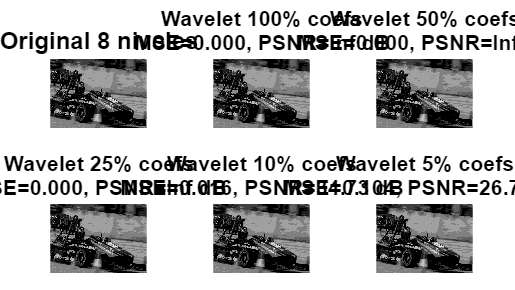

Wavelet 100% -> K=1830400, Rc≈1.00, MSE=0.0000, PSNR=Inf dB
Wavelet 50% -> K=915200, Rc≈2.00, MSE=0.0000, PSNR=Inf dB
Wavelet 25% -> K=457600, Rc≈4.00, MSE=0.0000, PSNR=Inf dB
Wavelet 10% -> K=183040, Rc≈9.99, MSE=0.0165, PSNR=34.73 dB
Wavelet 5% -> K=91520, Rc≈19.98, MSE=0.1036, PSNR=26.75 dB


Error using nexttile
The layout does not have sufficient space.

%% 4.b) Wavelet 2D con porcentajes más extremos

img_double = double(img8_padded);
wname = 'haar';
level = 2;

[Cw, Sw] = wavedec2(img_double, level, wname);
total_coef = numel(Cw);

keep_ratios = [1 0.5 0.25 0.1 0.05 0.01];  % añadimos 5% y 1%

fig_wav = figure('Name','Reconstrucción Wavelet (Extrema)','NumberTitle','off');
set(fig_wav, 'Units','normalized', 'OuterPosition',[0 0 1 1], 'Color','w');
tiledlayout(2,3,'Padding','compact','TileSpacing','compact');

% Original
nexttile;
imshow(uint8(img8 * (256/8)), 'InitialMagnification','fit');
title('Original 8 niveles', 'FontSize',18,'FontWeight','bold');

bits_ref = rows_orig * cols_orig * 3;
L = 8; max_val = L - 1;

for i = 1:length(keep_ratios)
    kr = keep_ratios(i);

    [~, idx_ord] = sort(abs(Cw), 'descend');
    K = max(1, round(kr * total_coef));

    mask = zeros(size(Cw));
    mask(idx_ord(1:K)) = 1;

    Cw_thr = Cw .* mask;
    img_rec_w = waverec2(Cw_thr, Sw, wname);
    img_rec_w = img_rec_w(1:rows_orig, 1:cols_orig);

    img_rec_q = round(img_rec_w);
    img_rec_q(img_rec_q < 0) = 0;
    img_rec_q(img_rec_q > max_val) = max_val;

    img_show = uint8(img_rec_q * (256/L));

    diff = double(img8) - double(img_rec_q);
    MSE = mean(diff(:).^2);
    if MSE == 0, PSNR = Inf; else, PSNR = 10*log10((max_val^2)/MSE); end

    bits_wav = K * 3;
    Rc = bits_ref / bits_wav;

    nexttile;
    imshow(img_show, 'InitialMagnification','fit');
    title(sprintf('Wavelet %.0f%% coefs\nMSE=%.3f, PSNR=%.2f dB', ...
          kr*100, MSE, PSNR), 'FontSize',16,'FontWeight','bold');

    fprintf('Wavelet %.0f%% -> K=%d, Rc≈%.2f, MSE=%.4f, PSNR=%.2f dB\n', ...
        kr*100, K, Rc, MSE, PSNR);
end

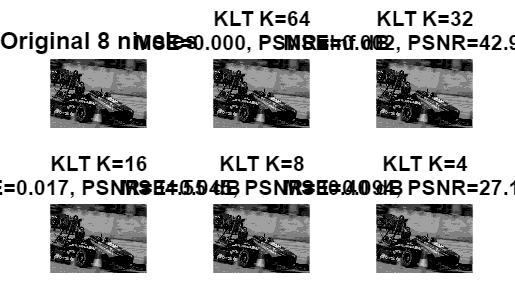

KLT K=64 -> Rc≈1.00, MSE=0.0000, PSNR=Inf dB
KLT K=32 -> Rc≈2.00, MSE=0.0025, PSNR=42.94 dB
KLT K=16 -> Rc≈4.00, MSE=0.0172, PSNR=34.55 dB
KLT K= 8 -> Rc≈7.99, MSE=0.0447, PSNR=30.40 dB
KLT K= 4 -> Rc≈15.99, MSE=0.0939, PSNR=27.18 dB


Error using nexttile
The layout does not have sufficient space.

%% 4.c) KLT 8x8 con K más extremos

% Bloques 8x8
B = im2col(img8_padded, [8 8], 'distinct');  % 64 x num_bloques
num_bloques = size(B,2);

mu = mean(B, 2);
Bz = B - mu;

Cklt = (Bz * Bz.') / num_bloques;
[V,D] = eig(Cklt);
[lambda, idx] = sort(diag(D), 'descend');
V = V(:, idx);

K_vals = [64 32 16 8 4 2];

fig_klt = figure('Name','Reconstrucción KLT (Extrema)','NumberTitle','off');
set(fig_klt, 'Units','normalized', 'OuterPosition',[0 0 1 1], 'Color','w');
tiledlayout(2,3,'Padding','compact','TileSpacing','compact');

% Original
nexttile;
imshow(uint8(img8 * (256/8)), 'InitialMagnification','fit');
title('Original 8 niveles', 'FontSize',18,'FontWeight','bold');

bits_ref = rows_orig * cols_orig * 3;
L = 8; max_val = L - 1;

for i = 1:length(K_vals)
    K = K_vals(i);

    Vk = V(:,1:K);
    Y = Vk' * Bz;
    B_hat = Vk * Y + mu;

    img_rec_padded = col2im(B_hat, [8 8], size(img8_padded), 'distinct');
    img_rec = img_rec_padded(1:rows_orig, 1:cols_orig);

    img_rec_q = round(img_rec);
    img_rec_q(img_rec_q < 0) = 0;
    img_rec_q(img_rec_q > max_val) = max_val;

    img_show = uint8(img_rec_q * (256/L));

    diff = double(img8) - double(img_rec_q);
    MSE = mean(diff(:).^2);
    if MSE == 0, PSNR = Inf; else, PSNR = 10*log10((max_val^2)/MSE); end

    coefs_tot = num_bloques * K;
    bits_klt = coefs_tot * 3;
    Rc = bits_ref / bits_klt;

    nexttile;
    imshow(img_show, 'InitialMagnification','fit');
    title(sprintf('KLT K=%d\nMSE=%.3f, PSNR=%.2f dB', ...
          K, MSE, PSNR), 'FontSize',16,'FontWeight','bold');

    fprintf('KLT K=%2d -> Rc≈%.2f, MSE=%.4f, PSNR=%.2f dB\n', ...
        K, Rc, MSE, PSNR);
end